# Передача ЧМ стерео сигналов

# Broadcast Transmitter

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Введение

Рассмотрим как в широковещательном FM-радио реализовано формирование стерео сигналов. Стерео сигнал сигнал - это сигнал который имеет две отдельные звуковые дорожки для левого и правого уха. Поэтому, чтобы его передать нужно организовать два канала связи. В FM-радио это делает с помощью метода объединения сигналов, который называется частотным мультиплексирование.

Сначала формируются два промежуточных сигнала: суммарный и разностный. Суммарный сигнал представляет из себя сумму канал для правого и левого уха. А разностный получается вычитанием из канала для левого уха канала для правого. 

Эти сигналы далее фильтруется низкочастотными фильтрами с полосой 15 kHz. Суммарный сигнал далее остается на нулевой частоте. Этот сигнал воспроизводится, если приемник слушателя работает в моно режиме. Разностный сигнал переносится на частотк 38 kHz. Это выполняется с помощью амплитудного модулятора с подавленной несущей (DSB-SC).

Чтобы упростить устройство приемника к суммарному и разностному сигналам добавляется гармонический пилот-сигнал с частотой 19 kHz. Данный сигнал подается в  приемнике на PLL, чтобы восстановить несущей DSB-SC сигнала. Каждый из сигналов умножается на свой коэффициент усиления: суммарный и разностный сигналы на 0.45, а пилот - на 0.1. Спектр мультиплексированного сигнала в упрощенном виде представлен ниже: 

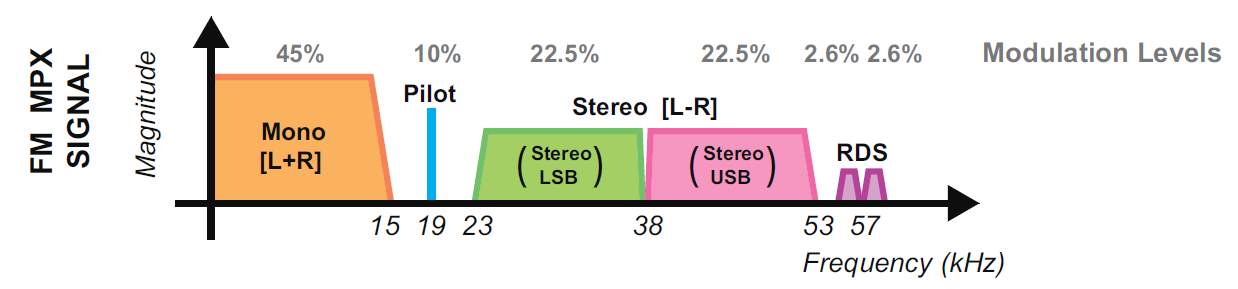

На рисунке также представлен сигнал RDS (Radio Data System). Это сигнал с BPSK модуляцией, и он используется для передачи в цифровом виде информации о радиостанцие. В дальнейшем для простоты мы его рассматривать не будем.

Далее мультплексированный сигнал частотно-модулируется с девиацией 75 kHz и переносится на нужную несущую частоту. Перед модуляцией верхние частоты сигнала дополнительно усиливаются. Данная процедура называется preempahsing. Для простоты это также рассматривать не будем.

Таким образом, схему передатчика FM стерео сигналов можно представить в виде:

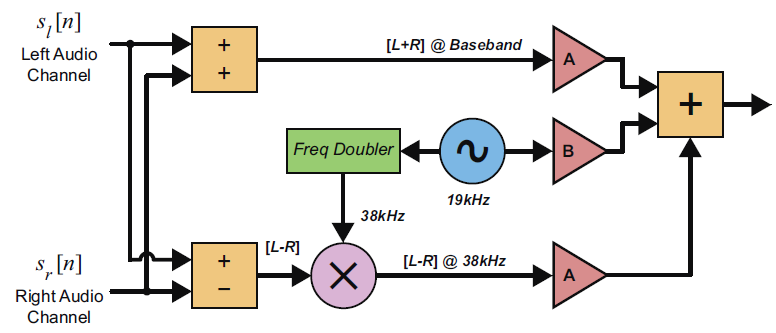

### 2. Реализация передатчика стерео сигналов в Matlab

Ниже представлен скрипт, выполняющий все описанные выше преобразования. В файле Audio_Source.wav записано звуковое стерео сообщение с частотой дискретизации $f_s =44\ldotp 1$ kHz. Чтобы избежать наложения спектров, его частота дискретизации увеличивается в  раз. Далее из него формируются суммарный и разностный сигналы. С помощью умножения на комплексную экспоненту с частотой 38 kHz разностный сигнал переносится по частоте. Суммарный, разностный и пилотный (19 kHz) сигналы умножаются на свои коэффициенты усиления и складываются. Так получается мультиплексированный сигнал.

Перед частотной модуляцией частота дискретизации опять увеличивается в 5 раз, чтобы избежать наложения спектров. Модуляция выполняется прямым методом с коэффициентом чувствительности 75e3 Hz/V. Для передачи модулированный сигнал остается только перенести на нужную несущую частоту.

После запуска скрипт можно увидеть спектры мультиплексированного и модулированного сигналов.

clc; clear; close all;
addpath('matlab/broadcast');

AudioFrameSize = 512;    % количество отсчетов аудиосигнала, получаемых за один раз
MuxRateRatio = 5;        % коэффициент увеличения частоты дискретизации до мультиплексирования каналов
ModRateRatio = 5;        % коэффициент увеличения частоты дискретизации до частотной модуляции
Kf = 75e3;               % чувствительность модулятора

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    'wav/Audio_Source.wav', ...
    'SamplesPerFrame',AudioFrameSize...
    );

% дополнительные расчеты
AudioFs = AudioReader.SampleRate;               % получаем частоту дискретизации аудиосообщения

MuxFs = AudioFs * MuxRateRatio;                 % частота дискретизации мультиплексированного сигнала
MuxFrameSize = AudioFrameSize * MuxRateRatio;   % количество отсчетов после мультиплексирования

ModFs = MuxFs * ModRateRatio;                   % частота дискретизации модулированного сигнала
ModFrameSize = MuxFrameSize * ModRateRatio;     % количество отсчетов после модуляции

% интерполятор 
Upsampler_1 = dsp.SampleRateConverter(...
    'Bandwidth', 40e3, ...
    'InputSampleRate',AudioFs, ...
    'OutputSampleRate', MuxFs ...
    );

Upsampler_2 = dsp.SampleRateConverter(...
    'Bandwidth', 110e3, ...
    'InputSampleRate',MuxFs, ...
    'OutputSampleRate', ModFs ...
    );

% генератор для сдвига сигнала по частоте и пилот-сигнала
CarrierGenerator = dsp.SineWave(...
    'SampleRate', MuxFs,...
    'SamplesPerFrame', MuxFrameSize,...
    'Frequency', [19e3 38e3],...
    'ComplexOutput', true, ...
    'Amplitude', [1 1]);

% объекты для вычисления спектра
MuxSpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',MuxFs);

ModSpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',ModFs);

% объект для отрисовки графиков
MuxPlotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -MuxFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'Multiplexed Signal'}, ...
    'SampleIncrement', MuxFs/MuxFrameSize ...
    );

ModPlotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -ModFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', ModFs/ModFrameSize ...
    );

% начальная фаза интегратора
InitPhase = 0;

% запуск симуляции
while(true)
    % считывание отсчетов аудиосообщения и выделение одного канала из
    % стерео сигнала
    AudioData = AudioReader();

    % увеличение частоты дискретизации аудиосообщения
    MessageData = Upsampler_1(AudioData);

    % формирование суммарного и разностного сигналов
    SumData = MessageData(:,1) + MessageData(:,2);
    SubData = MessageData(:,1) - MessageData(:,2);
    
    % формирование пилота и несущей для разностного сигнала
    Carrier = CarrierGenerator();
    Pilot = Carrier(:,1);
    DSBCarrierPilot = Carrier(:,2);
    
    % перенос разностного сигнала по частоте и мультиплексирование
    MuxData = 0.45*SumData + 0.45*SubData.*DSBCarrierPilot + 0.1*Pilot;
    MuxData = real(MuxData);
    MuxSpectrumData = MuxSpecEstimator(MuxData);
    MuxPlotter(MuxSpectrumData)

    % увиличение частоты дискретизации
    ModData = Upsampler_2(MuxData);
    
    % вычисление мгновенной частоты (Hz) и фазы
    freq = Kf * ModData;
    phase = InitPhase + 2*pi/ModFs * cumsum(freq);
    InitPhase = phase(end);
    
    % формирование модулированного сигнала
    FmSignal = cos(phase);
    ModSpectrumData = ModSpecEstimator(FmSignal);
    ModPlotter(ModSpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.05)
end

### 3. Реализация передатчика стерео сигналов в Simulink

В файле FM_Broadcast_Transmitter.slx представлена Simulink-модель, реализующая передатчик стерео сигналов. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

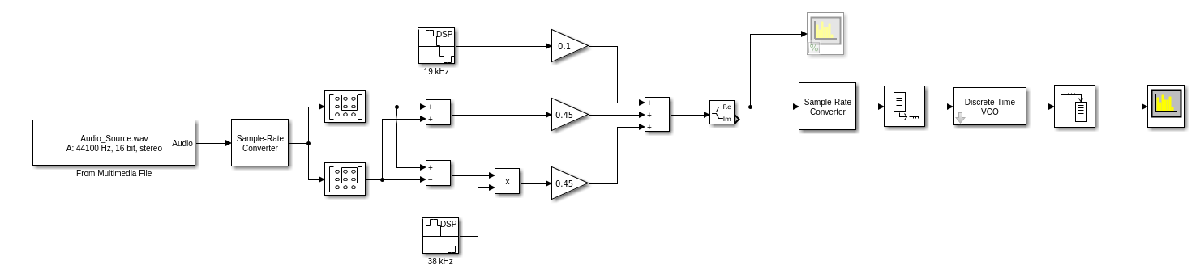

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR